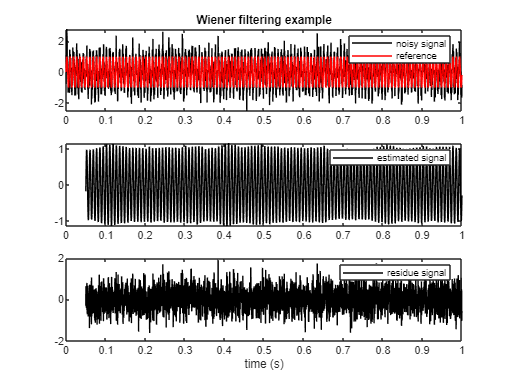

clear
close all
clc
fs = 4000; % sampling frequency
T = 1;% total recording time
L = T .* fs; % signal length
tt = (0:L-1)/fs; % time vector
ff = (0:L-1)*fs/L;
y = sin(2*pi*120 .* tt); y = y(:); % reference sinusoid
x = 0.50*randn(L,1) + y; x = x(:); % sinusoiud with additive Gaussian noise
N = 200; % filter order
[xest,b,MSE] = wienerFilt(x,y,N);
% plot results
figure
subplot(311)
plot(tt,x,'k'), hold on, plot(tt,y,'r')
title('Wiener filtering example')
legend('noisy signal','reference')
subplot(312)
plot(tt(N+1:end),xest,'k')
legend('estimated signal')
subplot(313)
plot(tt(N+1:end),(x(N+1:end) - xest),'k')
legend('residue signal')
xlabel('time (s)')

function [xest,B,MSE] = wienerFilt(x,y,N)
%
% Wiener filter based on Wiener-Hopf equations
%   This function takes as inputs a noisy signal, x, and a reference signal, y,
%   in order to compute a N-order linear filter that provides an estimate of y
%   from x
%  
% INPUTS
% x = noisy signal
% y = reference signalsinit
% N = filter order
%
% OUTPUTS
% xest = estimated signal
% b = Wiener filter coefficents
% MSE = mean squared error
%
% M. Buzzoni
% May 2019
% -------------
% Rev. Feb. 2020: the function can be performed by using column or row
% vectors as inputs
X = 1/N .* fft(x(1:N));
Y = 1/N .* fft(y(1:N));
X = X(:);
Y = Y(:);
Rxx = N .* real(ifft(X .* conj(X))); % Autocorrelation function
Rxy = N .* real(ifft(X .* conj(Y))); % Crosscorrelation function
Rxx = toeplitz(Rxx);
Rxy = Rxy';
B = Rxy / Rxx; B = B(:); % Wiener-Hopf eq. B = inv(Rxx) Rxy
xest = fftfilt(B,x);
xest = xest(N+1:end); % cut first N samples due to distorsion during filtering operation
MSE = mean(y(N+1:end) - xest) .^2; % mean squared error
end